function P = barycentric_interpolation(x, y, value)
    n = length(x);
    w = ones(1, n);

    for i = 1:n
        for j = 1:n
            if i ~= j
                w(i) = w(i) / (x(i) - x(j));
            end
        end
    end

    numerator = sum((w .* y) ./ (value - x));
    denominator = sum(w ./ (value - x));
    P = numerator / denominator; 
end

x = [1940, 1950, 1955, 1960, 1970, 1980]; 
y = [122201, 132670, 150646, 179300, 202210, 224505];


v1 = 1965

v1 = 1965

v2 = 1990

v2 = 1990


P1 = barycentric_interpolation(x, y, v1);
P2 = barycentric_interpolation(x, y, v2);

disp(['Estimated population in 1965: ', num2str(P1)]);

Estimated population in 1965: 200727.3437


disp(['Estimated population in 1990: ', num2str(P2)]);

Estimated population in 1990: 907490.6667


x = [196, 225, 256]; 
y = [14, 15, 16];

v = 219;

P = barycentric_interpolation(x, y, v);

disp(['Estimated sqrt(219): ', num2str(P)]);

Estimated sqrt(219): 14.7982


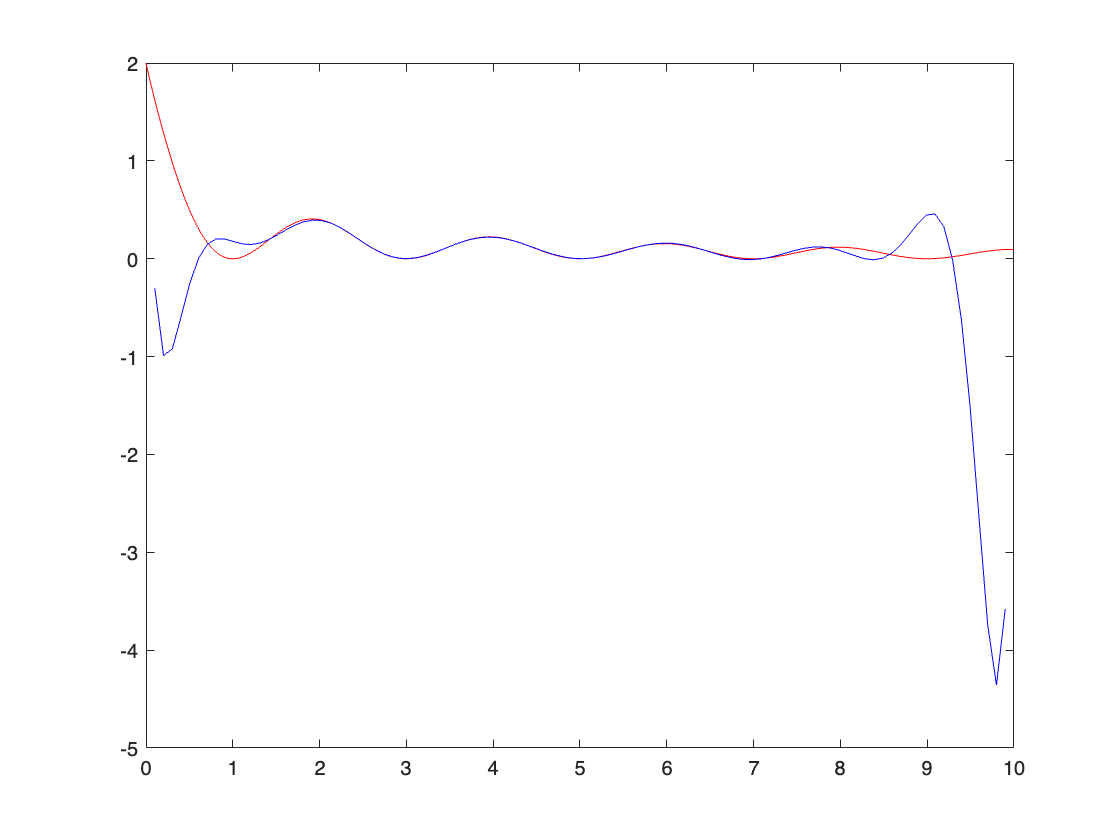

x=0:0.01:10;
f = (1 + cos(pi * x)) ./ (1 + 2*x);

x_nodes = linspace(0, 10, 15);
y_nodes = (1 + cos(pi * x_nodes)) ./ (1 + 2*x_nodes);

x_plot = linspace(0, 10, 100); 
y_plot = zeros(size(x_plot)); 

for i = 1:length(x_plot)
    y_plot(i) = barycentric_interpolation(x_nodes, y_nodes, x_plot(i)); % Compute P(x)
end

figure;
plot(x, f, 'r', x_plot, y_plot, 'b');

x=-5:0.01:5;
f = 1 ./ (1 + x.^2);

n_values = [2, 4, 6, 8];

x_test = linspace(-5, 5, 100); 
y_test = 1 ./ (1 + x_test.^2);

errors = zeros(size(n_values)); 

for i = 1:length(n_values)
    n = n_values(i);
    
    x_nodes = linspace(-5, 5, n+1); 
    y_nodes = 1 ./ (1 + x_nodes.^2);

    y_interp = zeros(size(x_test));
    for j = 1:length(x_test)
        y_interp(j) = barycentric_interpolation(x_nodes, y_nodes, x_test(j));
    end

    errors(i) = max(abs(y_test - y_interp));
end

disp([n_values' errors']);

    2.0000    0.6460
    4.0000    0.4383
    6.0000    0.6164
    8.0000    1.0451



x = -5:0.01:5; 
f_values = f_function(x);

x_test = linspace(-5, 5, 1000); 
y_test = f_function(x_test); 

errors_chebyshev1 = zeros(1, 21);
errors_chebyshev2 = zeros(1, 21);

for i = 0:20
   
    x_chebyshev1 = 5 * cos((i * pi) / 20);
    y_chebyshev1 = f_function(x_chebyshev1);

    x_chebyshev2 = 5 * cos(((2 * i + 1) * pi) / 42);
    y_chebyshev2 = f_function(x_chebyshev2);

    y_interp_chebyshev1 = zeros(size(x_test));
    y_interp_chebyshev2 = zeros(size(x_test));

    for j = 1:length(x_test)
        y_interp_chebyshev1(j) = barycentric_interpolation(x_chebyshev1, y_chebyshev1, x_test(j));
        y_interp_chebyshev2(j) = barycentric_interpolation(x_chebyshev2, y_chebyshev2, x_test(j));
    end

    errors_chebyshev1(i + 1) = max(abs(y_test - y_interp_chebyshev1));
    errors_chebyshev2(i + 1) = max(abs(y_test - y_interp_chebyshev2));
end
disp([errors_chebyshev1' errors_chebyshev2']);

    0.9615    0.9613
    0.9606    0.9596
    0.9576    0.9559
    0.9520    0.9493
    0.9424    0.9386
    0.9259    0.9204
    0.8962    0.8880
    0.8374    0.8247
    0.7048    0.6847
    0.5820    0.6045
    0.9615    0.9615
    0.5820    0.6045
    0.7048    0.6847
    0.8374    0.8247
    0.8962    0.8880
    0.9259    0.9204
    0.9424    0.9386
    0.9520    0.9493
    0.9576    0.9559
    0.9606    0.9596
    0.9615    0.9613



function y = f_function(x)
    y = 1 ./ (1 + x.^2);
end